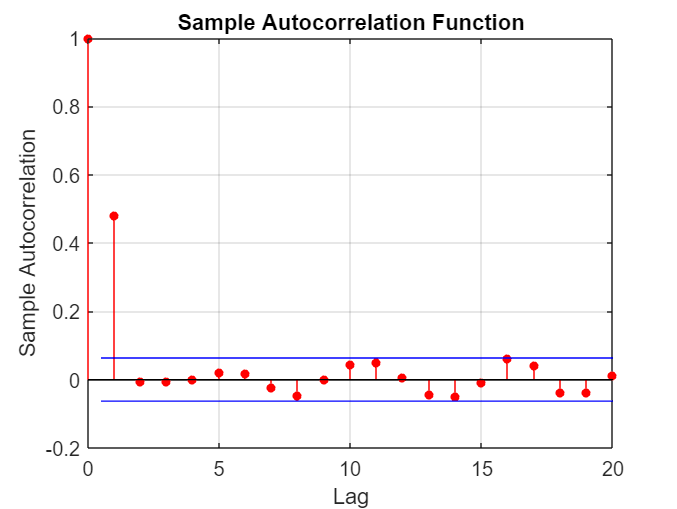

Md1 = arima('Constant', 0, 'MA', {0.8}, 'MALags', [1], 'Variance', 0.2);
Y_ma = simulate(Md1, 1000, 'NumPaths', 100);
autocorr(Y_ma(:,1))

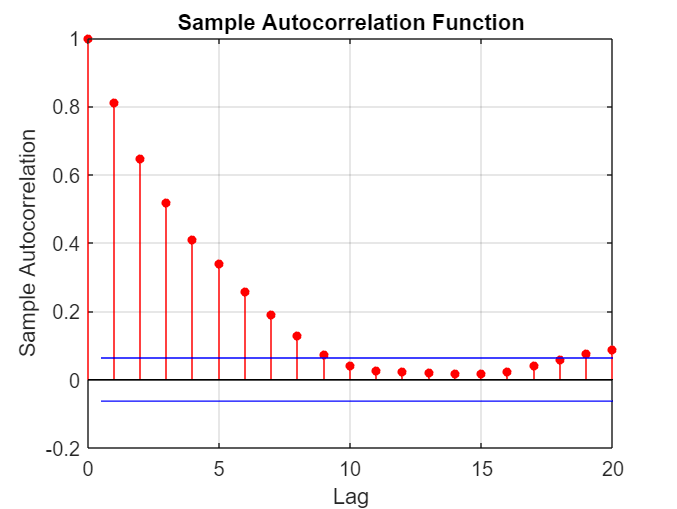

Md1 = arima('Constant', 0, 'AR', {0.8}, 'ARLags', [1], 'Variance', 0.2);
Y_ma = simulate(Md1, 1000, 'NumPaths', 10);
autocorr(Y_ma(:,1))

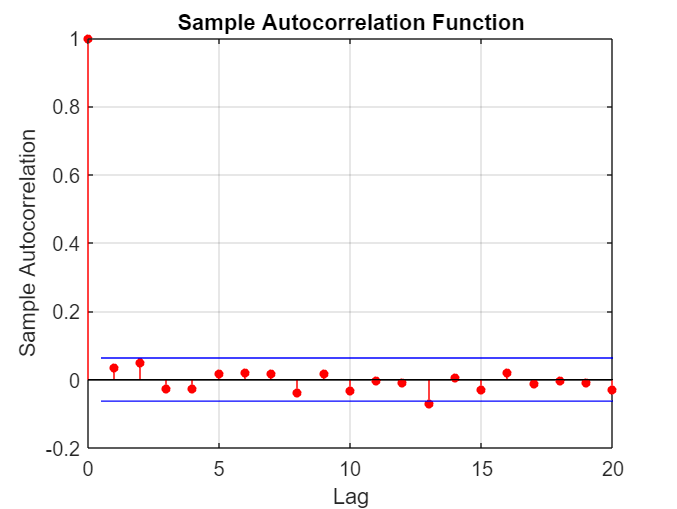

N = 1000;
R = 1000;
X_gwn = randn(N,R);
autocorr(X_gwn(:,1))

N = 100; % Sample Size
x = 25; % true mean
vk = 0.5*randn(N,1); %GWN
yk = x + vk; %Signal

mu_1 = mean(yk)

mu_1 = 24.9784

mu_2 = median(yk)

mu_2 = 24.9436

fprintf('Sample mean: %4.3f \nSample Median: %4.3f \n', mu_1, mu_2)

Sample mean: 24.978 
Sample Median: 24.944 




N = 100; % Sample Size
R = 300;
x = 25; % true mean
vk = 0.5*randn(N,R); %GWN
yk = x + vk; %Signal

m_1R = mean(yk,1)

m_1R =    24.8873   25.0388   24.9443   24.9495   25.0272   24.9728   24.9782   25.0159   25.0372   25.0822   24.9910   24.9794   25.0073   24.9726   24.9150   24.9835   24.9847   25.0201   25.0696   25.0303   24.9499   25.0523   25.0284   24.9731   25.0325   24.9408   24.9677   25.0144   25.0638   24.8846   25.0500   25.1054   25.0031   24.9801   24.9451   24.9928   24.9361   25.0570   24.9608   25.0102   24.9649   24.9610   24.9605   25.0177   25.1332   24.9344   24.9994   25.0727   24.8974   25.0399


m_2R = median(yk,1)

m_2R =    24.8997   25.0490   24.9367   24.8789   25.0489   24.9159   25.0025   25.0607   24.9903   25.1106   25.0115   24.9157   25.0622   24.9996   24.9014   24.9369   25.0221   25.0328   25.0326   25.1087   24.9775   25.0681   25.0390   24.9925   24.9997   24.9115   24.9889   24.9895   25.1112   24.8742   25.0402   25.1240   24.9910   24.9911   24.9767   24.9965   24.8754   25.0301   24.9382   24.9954   24.9987   24.9350   24.9653   24.9802   25.1288   24.9260   24.9882   24.9813   24.8456   25.1558



mu_1 = mean(m_1R)

mu_1 = 24.9972

mu_2 = mean(m_2R)

mu_2 = 24.9986


bias1 = mu_1 - x

bias1 = -0.0028

bias2 = mu_1 - x

bias2 = -0.0028

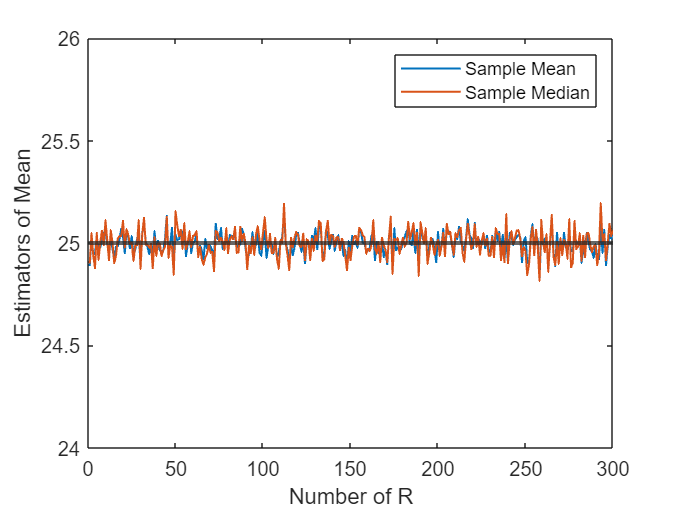

plot(m_1R, 'LineWidth', 1)
hold on;
plot(m_2R, 'LineWidth', 1)
hold off;
yline(x, 'LineWidth', 2)
ylim([24 26]);
xlabel("Number of R")
ylabel("Estimators of Mean")
legend('Sample Mean', 'Sample Median')

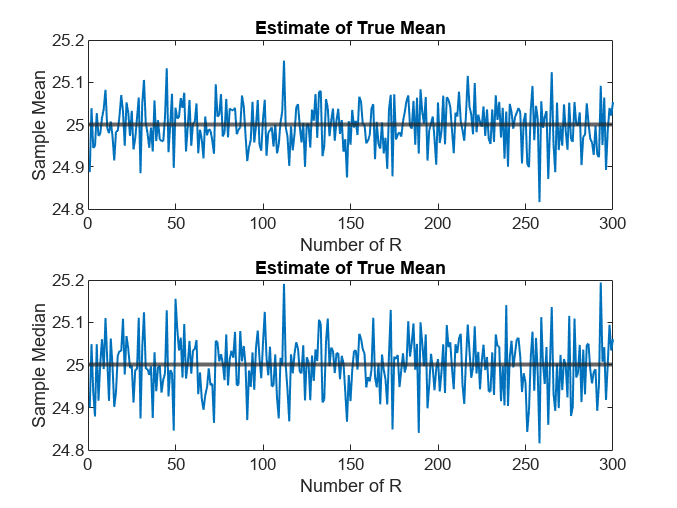


figure
subplot(2,1,1)
plot(m_1R, 'LineWidth', 1)
yline(x, 'LineWidth', 2)
xlabel("Number of R")
ylabel("Sample Mean")
title("Estimate of True Mean")

subplot(2,1,2)
plot(m_2R, 'LineWidth', 1)
yline(x, 'LineWidth', 2)
xlabel("Number of R")
ylabel("Sample Median")
title("Estimate of True Mean")

var_mu1 = var(m_1R)

var_mu1 = 0.0028

var_mu2 = var(m_2R)

var_mu2 = 0.0044

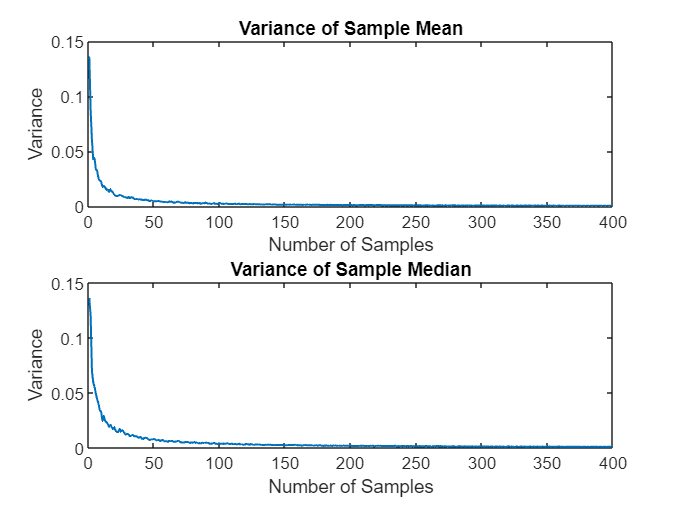


n = 400; % change in sample size 
var_mu1_n = zeros(n-1,1);
var_mu2_n = zeros(n-1,1);

for i = 1:n-1
    vk2 = 0.5*randn(i+1,R);
    yk2 = x + vk2;
    var_mu1_n(i,1) = var(mean(yk2));
    var_mu2_n(i,1) = var(median(yk2));
end

figure
subplot(2,1,1)
plot(var_mu1_n, 'LineWidth', 1)
xlabel("Number of Samples")
ylabel("Variance")
title("Variance of Sample Mean")

subplot(2,1,2)
plot(var_mu2_n, 'LineWidth', 1)
xlabel("Number of Samples")
ylabel("Variance")
title("Variance of Sample Median")